# Problem 1 Part 1 

Write a MATLAB code to generate a sinusoid signal with an amplitude of 0.5 a.u. (arbitrary unit) and frequency of 0.5 Hz. Plot the analog signal as a function of time.

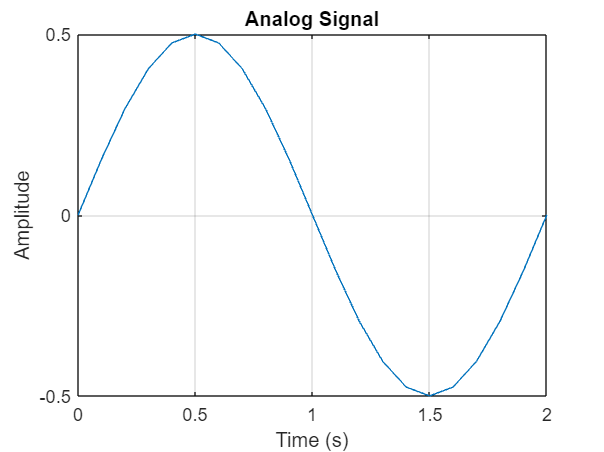

clear
clc
% Parameters
A = 0.5;  % Amplitude in arbitrary units
f = 0.5;  % Frequency in Hz
w = f*2*pi; % Angular frequency
T = 1/f; % Period

% Generate sinusoid signal
t = 0:0.1:T;
signal = A*sin(w*t);

% Plot the signal
figure;
plot(t, signal);
xlabel('Time (s)');
ylabel('Amplitude');
title('Analog Signal');
grid on;

# Problem 1 Part 2 and 3

Sample the signal with a sampling time, 𝑇𝑠 of 0.1 second. Plot the sampled signal as a function of sample number, n. Report the sampling frequency of the discrete-time signal.

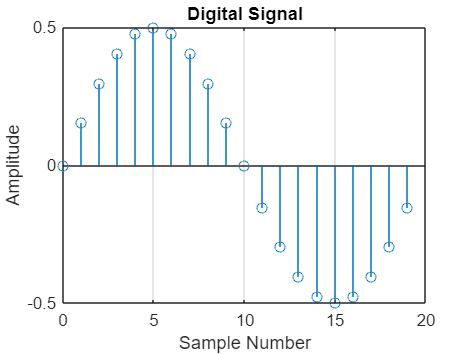

% Parameters
A = 0.5;  % Amplitude in arbitrary units
f = 0.5;  % Frequency in Hz
w = f*2*pi; % Angular frequency
Ts = 0.1; % Sampling Period
N = (2*pi)/(w*Ts);
T = 1/f; % Period

% Generate sinusoid signal
n = 0:N-1;
t_sampled = n*Ts;
sampled_signal = A*sin(w*t_sampled);

% Plot the signal
stem(n, sampled_signal, 'Marker', 'o');
xlabel('Sample Number');
ylabel('Amplitude');
title('Digital Signal');
grid on;


% Sampling frequency
fs = 1/Ts; % This = 10

# Problem 2

Write a MATLAB code (use sound.m) to generate a laughter signal. Plot the first 50 ms of the signal as a function of time. Report the sampling period of the signal. Plot the signal as a function of the sample number, when the sampling period is doubled (hint: look into the built-in ‘downsample’ function).

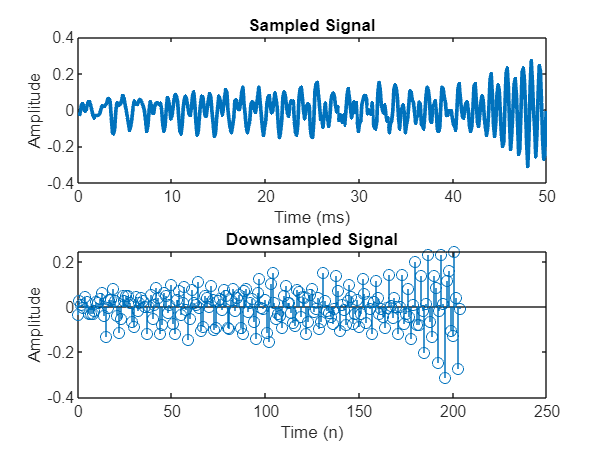

clear
clc
% Load the laughter file
laughter = load('laughter');

% Sets the time to sample the frequency in milliseconds
t = (1:length(laughter.y))/laughter.Fs*1000;
t_subset = t(t<50);
y_subset = laughter.y(t<50);

% Plot frequency over time
subplot(2,1,1);
plot(t_subset, y_subset, 'LineWidth', 2);
xlabel('Time (ms)');
ylabel('Amplitude');
title('Sampled Signal');

Ts = laughter.Fs^-1;
T = 0.05;
N = round(T/Ts);
downsampled_N = round(T/(2*Ts));
n = 0:(downsampled_N-1);
wave = laughter.y(1:N);
downsampled_wave = downsample(wave,2);

%Plot downsampled signal
subplot(2,1,2);
stem(n, downsampled_wave);
xlabel('Time (n)');
ylabel('Amplitude');
title('Downsampled Signal');

# Problem 3

Define and plot p[n], given that 𝑎−3 = 0.5, 𝑎1 = 1, 𝑎2 = 3, 𝑎7 = 2;

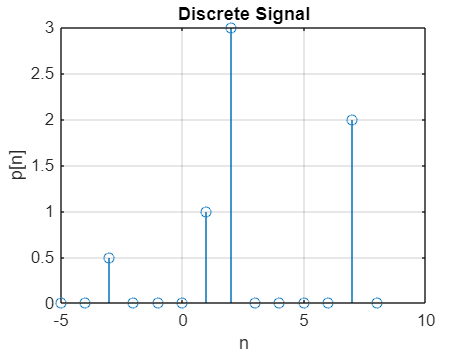

clear
clc
% Set the discrete values
n = [-5 -4 -3 -2 -1 0 1 2 3 4 5 6 7 8];
a = [0 0 0.5 0 0 0 1 3 0 0 0 0 2 0];

% Plot the signal
stem(n, a, 'Marker', 'o');
xlabel('n');
ylabel('p[n]');
title('Discrete Signal');
grid on;

# Problem 4

Show that 𝑢[𝑛] = 𝛿[𝑛] + 𝛿[𝑛 − 1] + 𝛿[𝑛 − 2] + ⋯. Write a MATLAB code to:

a. plot the original and delayed impulse functions, and

b. add the impulse functions to plot the unit step function.

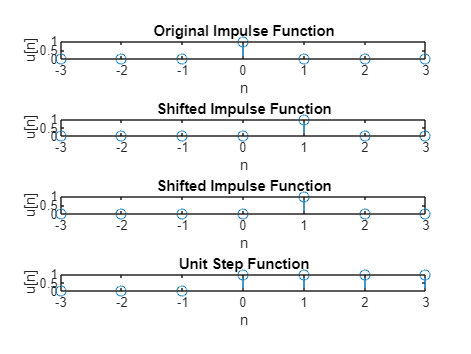

clear
clc

x = -3:1:3;

% Original impulse function
y1 = dirac(x);
idx = y1 == Inf; % find Inf
y1(idx) = 1;     % set Inf to finite value
subplot(4, 1, 1);
stem(x, y1);
xlabel('n');
ylabel('u[n]');
title('Original Impulse Function');

% First Shifted impulse function
y2 = dirac(x-1);
idx = y2 == Inf; % find Inf
y2(idx) = 1;     % set Inf to finite value
subplot(4, 1, 2);
stem(x, y2);
xlabel('n');
ylabel('u[n]');
title('Shifted Impulse Function');

% Second Shifted impulse function
y3 = dirac(x-1);
idx = y3 == Inf; % find Inf
y3(idx) = 1;     % set Inf to finite value
subplot(4, 1, 3);
stem(x, y3);
xlabel('n');
ylabel('u[n]');
title('Shifted Impulse Function');

% Unit Step function
u = cumsum(y1);
subplot(4, 1, 4);
stem(x, u);
xlabel('n');
ylabel('u[n]');
title('Unit Step Function');

# Problem 5

Express 𝛿[𝑛 − 5] as the first backward difference of the corresponding unit step sequences. Write a MATLAB code:

a. to plot the corresponding unit step sequences.

b. Compute the first backward difference of the step functions to generate and plot the impulse function.

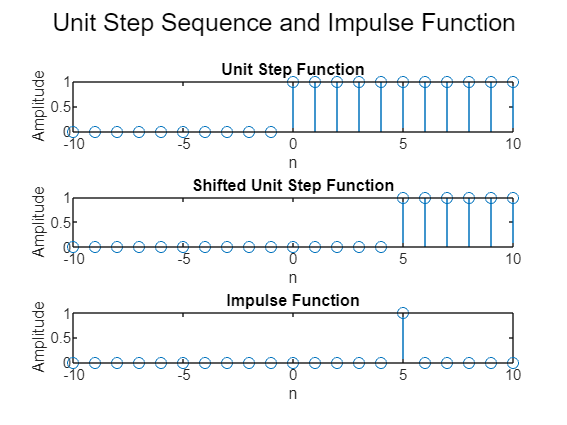

clear
clc

% Create unit step function
n = -10:10;
u = zeros(size(n));
u_shifted = zeros(size(n));
u(n >= 0) = 1;
u_shifted(n >= 5) = 1;
backward_diff = [0, diff(u_shifted)];

% Plot the original unit step function
subplot(3, 1, 1);
stem(n, u);
xlabel('n');
ylabel('Amplitude');
title('Unit Step Function');

% Plot the shifted unit step function
subplot(3, 1, 2);
stem(n, u_shifted);
xlabel('n');
ylabel('Amplitude');
title('Shifted Unit Step Function');

% Plot the original unit step function
subplot(3, 1, 3);
stem(n, backward_diff);
xlabel('n');
ylabel('Amplitude');
title('Impulse Function');

# Problem 6

Design a module that generates a complex sequence with an exponentially decaying envelope. Plot the (a) real part, (b) imaginary part, (c) magnitude, and (d) phase angle of a sequence generated by the module.

Now design a module that will generate a shifted and magnified version of the previous sequence. Plot the (a) real part, (b) imaginary part, (c) magnitude, and (d) phase angle of the delayed and magnified sequence.

% Part 1 - Original Sequence
N = 240;
A = 47;
df = 0.7;
fs = 0.1;

fs = 0.1000

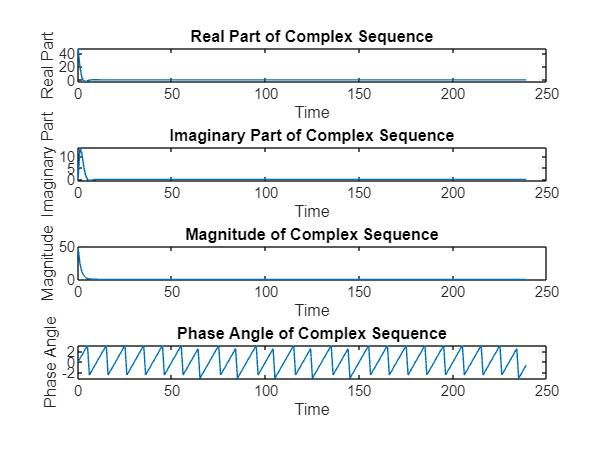

t = 0:N-1;
complex_sequence = A*exp(j*2*pi*fs*t).*exp(-df*t);
figure;

% a. Real Part
subplot(4,1,1);
plot(t, real(complex_sequence));
xlabel('Time');
ylabel('Real Part');
title('Real Part of Complex Sequence');

% b. Imaginary Part
subplot(4,1,2);
plot(t, imag(complex_sequence));
xlabel('Time');
ylabel('Imaginary Part');
title('Imaginary Part of Complex Sequence');

% c. Magnitude
subplot(4,1,3);
plot(t, abs(complex_sequence));
xlabel('Time');
ylabel('Magnitude');
title('Magnitude of Complex Sequence');

% d. Phase Angle
subplot(4,1,4);
plot(t, angle(complex_sequence));
xlabel('Time');
ylabel('Phase Angle');
title('Phase Angle of Complex Sequence');

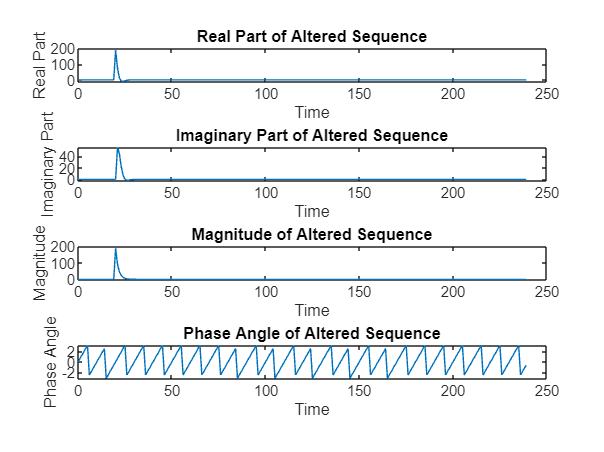


% Part 2 - Shift and Magnify
shift = 20;
magnify = 4;
new_sequence = circshift(complex_sequence, shift)*magnify;
figure;

% a. Real Part
subplot(4,1,1);
plot(t, real(new_sequence));
xlabel('Time');
ylabel('Real Part');
title('Real Part of Altered Sequence');

% b. Imaginary Part
subplot(4,1,2);
plot(t, imag(new_sequence));
xlabel('Time');
ylabel('Imaginary Part');
title('Imaginary Part of Altered Sequence');

% c. Magnitude
subplot(4,1,3);
plot(t, abs(new_sequence));
xlabel('Time');
ylabel('Magnitude');
title('Magnitude of Altered Sequence');

% d. Phase Angle
subplot(4,1,4);
plot(t, angle(new_sequence));
xlabel('Time');
ylabel('Phase Angle');
title('Phase Angle of Altered Sequence');

# Problem 7

Design a sinusoid sequence for which the period 𝑁=5. Plot the analog signal if the sampling period is 0.5 milliseconds. Plot the discrete signal on top of the analog signal.

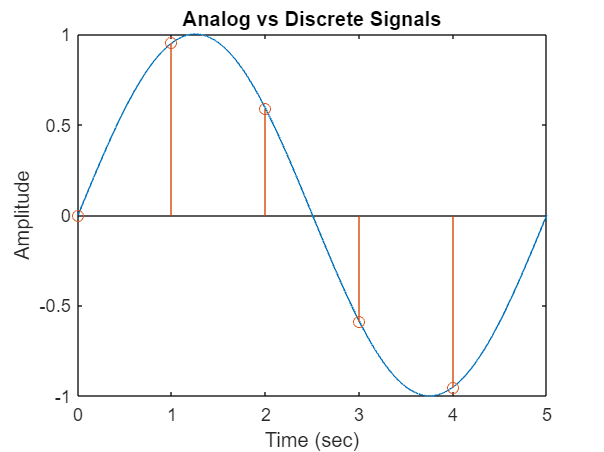

clear
clc

% Set initial parameters
N = 5; % Period
f = N^-1; % Frequency
Ts = 0.5*10^-3; % Sampling period
w = f*2*pi; % Angular frequency

% Create analog and discrete signals
n = 0:1:N-1;
t = 0:Ts:N;
analog = sin(w*t);
discrete = sin(w*n);

% Plot the signals on top of each other
figure;
plot(t,analog);
hold on
stem(n,discrete);
hold off
xlabel('Time (sec)');
ylabel('Amplitude');
title('Analog vs Discrete Signals');